# Comparison Example Part 1: Sampling from an Ansiotropic Gaussian Function

Author: Adolphus Lye (adolphus.lye@liverpool.ac.uk)

## Problem: 

This case study is based on the literature by [Goodman and Weare (2010)](https://projecteuclid.org/download/pdf_1/euclid.camcos/1513731992).

In this comparison example, we wish to demonstrate the affine-invariant property of the Ensemble sampler proposed by [Goodman and Weare (2010)](https://projecteuclid.org/download/pdf_1/euclid.camcos/1513731992). To highlight such property, we will be comparing the performance of the Ensemble sampler with Affine Invariance (ESAI) against the heaily-used Metropolis-Hastings (MH) sampler.

As a simple example, let us first consider an anisotropic Gaussian function which obeys the following equation:


$$$$$$

$$\pi \left(\mathit{\mathbf{x}}\right)\propto \mathrm{exp}\left\lbrack -\frac{{\left(x_1 -x_2 \right)}^2 }{2\cdot \epsilon }-\frac{{\left(x_1 +x_2 \right)}^2 }{2}\right\rbrack$$


whereby $\epsilon$ is the scaling factor which dictates the degree of anisotropy of $\pi \left(\mathit{\mathbf{x}}\right)$. Here, $\epsilon =0\ldotp 01$. An illustration of the target distribution $\pi \left(\mathit{\mathbf{x}}\right)$ is provided below:

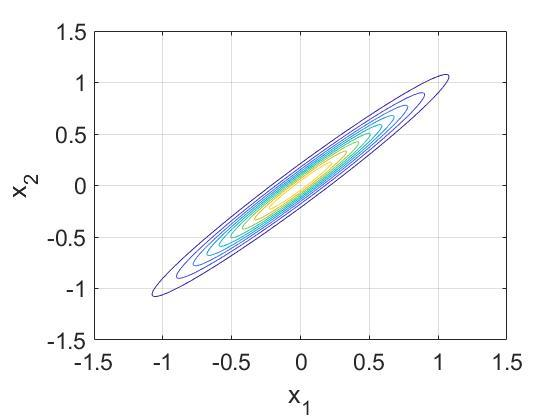

For each of the samplers, sampling from this target distribution will be done through initiating 4 sampling chains, each chain generating 2000 samples.

## 1) Setting-up the problem:

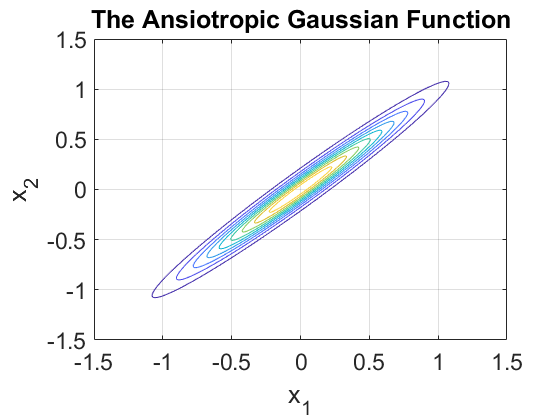

% Number of dimensions of the problem:
dim = 2; 

% Defining the scaling factor of the target distribution:
e = 0.01; 

% Defining the log-target distribution:
logPfun = @(x) -((((x(:,1) - x(:,2)).^2)./(2.*e)) + (((x(:,1) + x(:,2)).^2)./(2)));

% To generate an illustrative contour plot of the target distribution:
[X1,X2] = meshgrid(-2:.01:2,-2:.01:2);
Z = logPfun([X1(:) X2(:)]); 
Z = reshape(Z,size(X1));

figure();
hold on; box on; grid on;
contour(X1,X2,exp(Z))
colormap(parula)
title('The Ansiotropic Gaussian Function')
xlim([-1.5 1.5])
ylim([-1.5 1.5])
xlabel('x_1')
ylabel('x_2')
set(gca, 'fontsize', 17)

## 2) Sample using the Ensemble sampler:

### a) Defining the input parameters:

% Defining the total number of chains of the ensemble:
Nwalkers = 2*dim;  

% Defining the starting point of each chain:
start_emcmc = unifrnd(-4, 4, Nwalkers, dim);

% Defining the sample size per chain:
Nsamples_emcmc = 2000;

% Defining the burn-in length of each chain:
BurnIn_emcmc = 50;

% Defining the step-size of each chain:
step_size = 7; 
% Note: The step-size is chosen such that it gives the Ensemble sampler an
% overall acceptance rate that is close to 0.235.

### b) Initiate the Ensemble sampler:

tic;
EMCMC1 = EMCMCsampler(start_emcmc,logPfun,Nsamples_emcmc,'StepSize',step_size,'burnin',BurnIn_emcmc);

timeEMCMC_1 = toc;
fprintf('Time elapsed is for the Ensemble sampler for Anisotropic case: %f \n',timeEMCMC_1)

Time elapsed is for the Ensemble sampler for Anisotropic case: 1.250494 


fprintf('The acceptance level of the Ensemble sampler for Anisotropic case is %d. \n',EMCMC1.acceptance)

The acceptance level of the Ensemble sampler for Anisotropic case is 2.614019e-01. 


### c) To obtain the sample output:

% To extract the samples:
samps1_emcmc = EMCMC1.samples;

% Note that the output is in the form of a Nsamples x dim x Nwalker matrix.
% We need to flatten the chain and convert it to a N x dim matrix:
samples_emcmc_1 = permute(samps1_emcmc, [2 1 3]);
samples_emcmc_1 = samples_emcmc_1(:,:)';

## 3) Sample using the MH sampler:

### a) Defining the input parameters:

% Defining the total number of chains of the MH sampler:
Nchains = Nwalkers;  

% Defining the tuning parameter of the MH sampler:  
tuning_mh = [0.1, 0; 0, 0.1]; 
% Note: The tuning parameter is chosen such that it gives the MH sampler an
% overall acceptance rate that is close to 0.235.

% Defining the proposal function of the MH sampler:
proppdf = @(CandidateSample,CurrentSample) mvnpdf(CandidateSample,CurrentSample,tuning_mh);
proprnd = @(CurrentSample) mvnrnd(CurrentSample,tuning_mh);

% Defining the starting point of each chain:
start_mh = unifrnd(-4, 4, Nchains, dim);

% Defining the sample size per chain:
Nsamples_mh = 2000;

% Defining the burn-in length of each chain:
BurnIn_mh = 50;

### b) Initiate the Metropolis-Hastings sampler:

tic; 
[samps1_mh,accept_1] = mhsample(start_mh,Nsamples_mh,'logpdf',logPfun,'proppdf',proppdf...
    ,'proprnd',proprnd,'symmetric',1....
    ,'burnin',BurnIn_mh,'nchain',Nchains);
timeMH_1 = toc;
fprintf('The acceptance level of the MH sampler for Anisotropic case is %d. \n',accept_1)

The acceptance level of the MH sampler for Anisotropic case is 2.678049e-01. 
The acceptance level of the MH sampler for Anisotropic case is 2.551220e-01. 
The acceptance level of the MH sampler for Anisotropic case is 2.400000e-01. 
The acceptance level of the MH sampler for Anisotropic case is 2.556098e-01. 


fprintf('Time elapsed is for the MH sampler for Anisotropic case: %f \n',timeMH_1)

Time elapsed is for the MH sampler for Anisotropic case: 0.117857 


### c) To obtain the sample output:

% Note that the output is in the form of a Nsamples x dim x Nchains matrix.
% We need to flatten the chain and convert it to a N x dim matrix:
samples_mh_1 = permute(samps1_mh, [2 1 3]);
samples_mh_1 = samples_mh_1(:,:)';

## 3) Save the data:

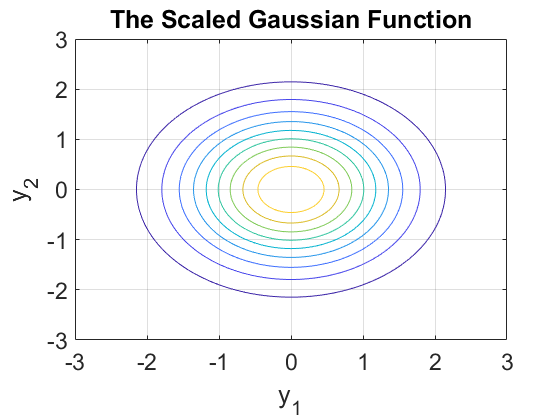

Time elapsed is for the Ensemble sampler for Anisotropic case: 2.335485 
The acceptance level of the Ensemble sampler for Anisotropic case is 2.635237e-01. 
The acceptance level of the MH sampler for Isotropic case is 1.609756e-02. 
The acceptance level of the MH sampler for Isotropic case is 2.048780e-02. 
The acceptance level of the MH sampler for Isotropic case is 1.707317e-02. 
The acceptance level of the MH sampler for Isotropic case is 2.146341e-02. 
Time elapsed is for the MH sampler for Isotropic case: 0.137183 


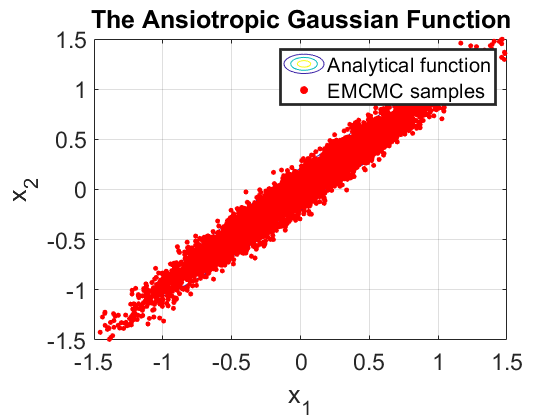

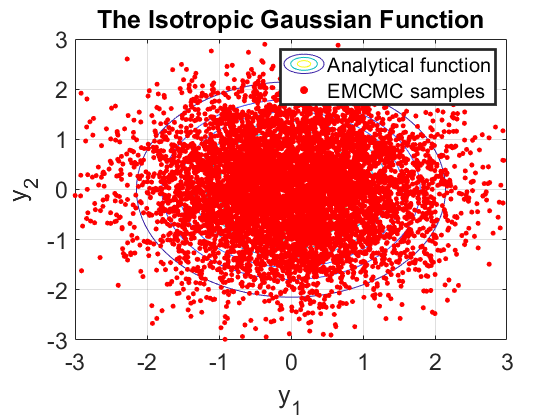

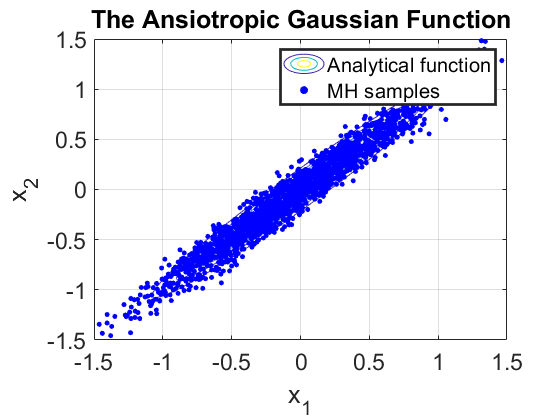

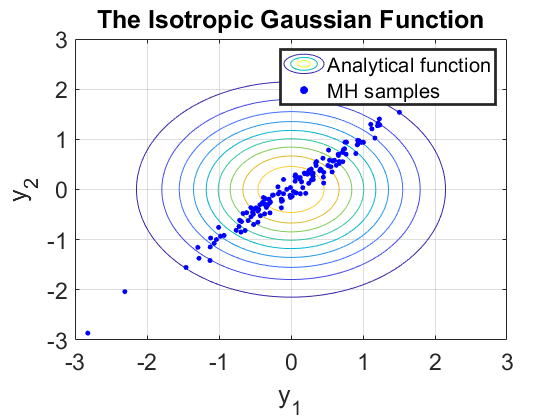

% To save all the data from this file:
save Example_Comparison_Part1.mat;

%%%%%%%%%%%%%%%%%%%%%%%%%%%% End of code %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%